clear
clc
close all

### Definition der Variablen

l = 1.5;
m = 5;
u = 4;
r = 0.06;
M = 0.2;
R = 1;
L = 0.0003;
psi = 0.09;
J = 7.2e-4;
g = 9.81;

### Definition der Übertrgungsfunktionen

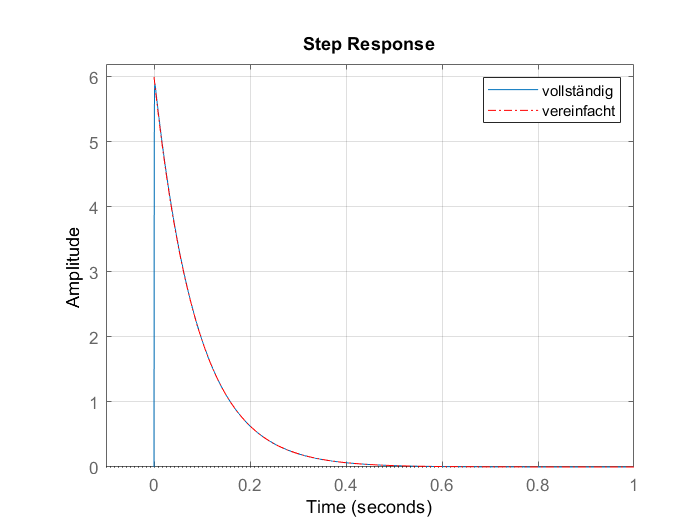

s = tf('s');

F = u/r*(J/psi)*s/...
    (1+J*R/(psi^2)*s+J*L/(psi^2)*s^2); %Vollständige Übertragungsfunktion des Stellglieds

Fe = u/r*(J/psi)*s/...
    (1+J*R/(psi^2)*s); %Vereinfachte Übertragungsfunktion des Stellglieds
% Vergleich der Reaktionen der vollständigen und vereinfachten
% Übertragungsfunktionen auf einen Einheitssprung

step(F)
hold on
step(Fe,"-.r")
legend("vollständig","vereinfacht")
xlim([-.1 1])
ylim([0 6.2])
grid on
saveas(gcf,"./Plots/vergleich_a.svg")

## b)

### Errechnen der gegbenen Parameter

a0 = (3*g*(M+m))/(l*(4*M+m));
b0 = 3/(l*(4*M+m));
a2 = 1;

bp = (3*g+m)/(4*M+m);
bf = (4/(4*M+m));

### Reglerbestimmung durch Polvorgabe

D = 0.7;
w0 = 9;
s3 = 3;
% Bestimmung der benötigten Pole

c3 = 1;
c2 = 2*D*w0+s3;
c1 = w0^2+2*s3*D*w0;
c0 = s3*w0^2;

c = [c3 c2 c1 c0]'

c =     1.0000
   15.6000
  118.8000
  243.0000



% Aufstellen der Sylvestermatrix
Syl = [a2 0 0 0;...
    0 a2 0 0;...
    -a0 0 b0 0;...
    0 -a0 0 b0];

% Lösen des Gleichungssystems
k = Syl\c

k = 	1.0e+03 *

    0.0010
    0.0156
    0.3955
    1.5005



% Definieren der einzelen Reglerparameter aus den Lösungsvektor, wobei 
% A -> alpha und B -> beta
A1 = k(1);
A0 = k(2);
B1 = k(3);
B0 = k(4);

% Einführen der Laplace-Variable 
s = tf('s');

% Definition von F_phi,Fx als Übertragungsfunktion der Regelstrecke
Fs = b0/(s^2-a0);

% Aufbau des Zusatandsraums der Regelstrecke

A = [0 1 0 0;...
    a0 0 0 0;...
    0 0 0 1;...
    bp 0 0 0];

B = [0;b0;0;bf];

C = [1 0 0 0;...
    0 0 1 0];

D = [0; 0];

x0 = [1/(180*pi) 0 0 0];

% Definition der Reglerübertragungsfunktion
Fr = (B1*s+B0)/(A1*s+A0)

Fr =
 
  395.5 s + 1500
  --------------
     s + 15.6
 
Continuous-time transfer function.



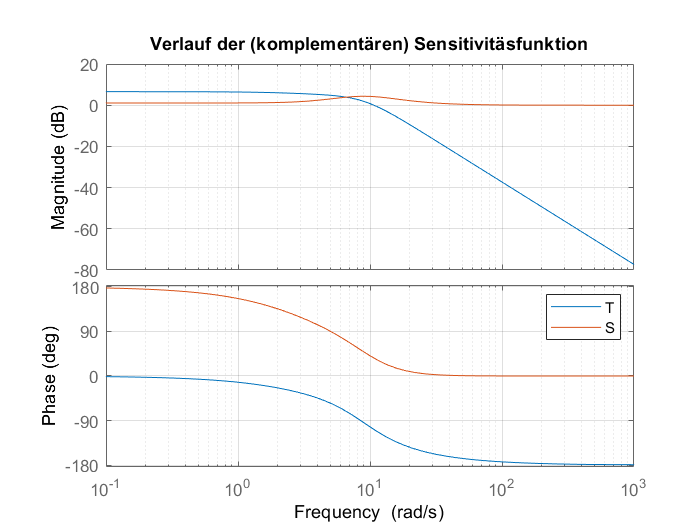


% Aufstelllen des geschlossen Regelkreises
T_num = Fr*Fs/(1+Fr*Fs);
S_num = 1/(1+Fr*Fs);
L = Fr*Fs;

T = minreal(T_num);
S = minreal(S_num);

figure()
bode(T)
hold on
bode(S)
hold off
legend("T","S")
title("Verlauf der (komplementären) Sensitivitäsfunktion")
grid on
saveas(gcf,"./Plots/Sensitivitaet_b.svg")

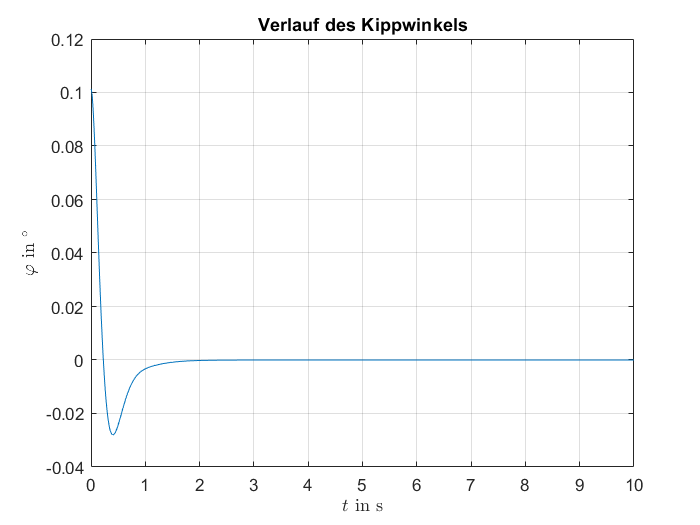

p0 = pi/180;

% Durchführen der Simulation
sim("Aufgabe2b")
sim("Aufgabe2c")
% Plotten des Verlaufs des Kippwinkels
figure()
plot(phi_b*180/pi)
title("Verlauf des Kippwinkels")
xlabel("$t$ in $\mathrm s$",'Interpreter','latex')
ylabel("$\varphi$  in  $^{\circ}$",'Interpreter','latex')
grid on
saveas(gcf,"./Plots/phi_b.svg")

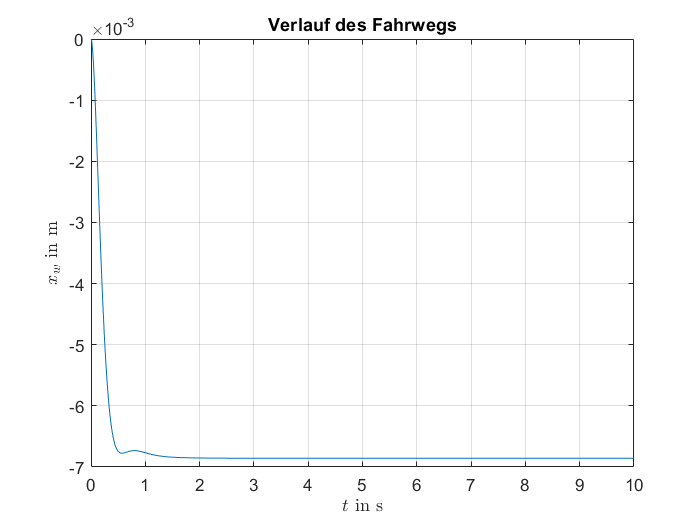


% Plotten des Verlaufs des Fahrwegs
figure()
plot(xw_b)
title("Verlauf des Fahrwegs")
xlabel("$t$ in $\mathrm s$",'Interpreter','latex')
ylabel("$x_w$  in  $\mathrm m$",'Interpreter','latex')
grid on
saveas(gcf,"./Plots/xw_b.svg")

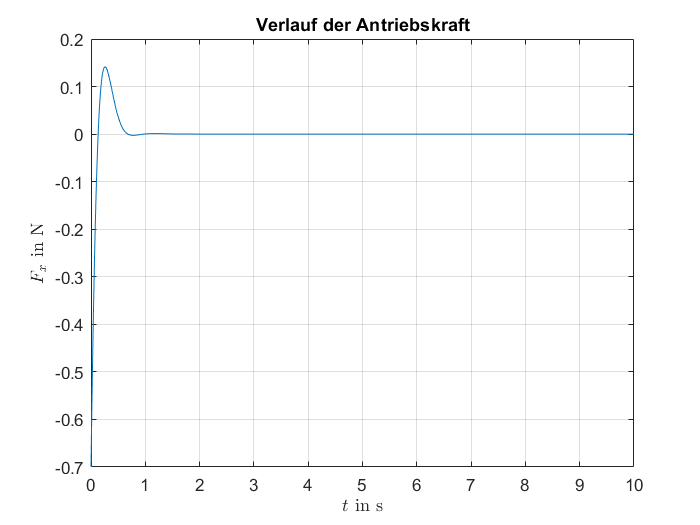


% Plotten des Verlaufs der Antriebskraft
figure()
plot(Fx_b)
title("Verlauf der Antriebskraft")
xlabel("$t$ in $\mathrm s$",'Interpreter','latex')
ylabel("$F_x$  in  $\mathrm N$",'Interpreter','latex')
grid on
saveas(gcf,"./Plots/Fx_b.svg")

## c)

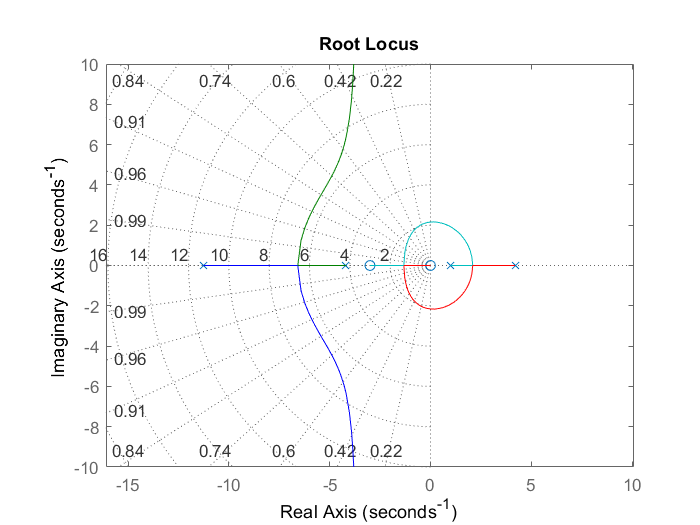

% Definition der geforderten Reglerfunktion (ohne Verstärkungsfaktor)
Fr2 = (s+3)/(s-1);

% Aufstellen des offenen Reglekreises
Lnum = Fr2*Fe*Fs;
L_1 = minreal(Lnum);

% Plot der Wurzelortskurve des offenen Regelkreises
figure()
rlocus(Lnum)
ylim([-10 10])
axis equal
grid on

% saveas(gcf,"./Plots/WOK_c.svg")




% Tool zum Ermitteln des Verstärkungsfaktors aus der Wurzelortskurve,
% auskommentiert da Popup Fenster störend ist

% [k,poles]=rlocfind(L_1)
 


### Vergleich der Regler

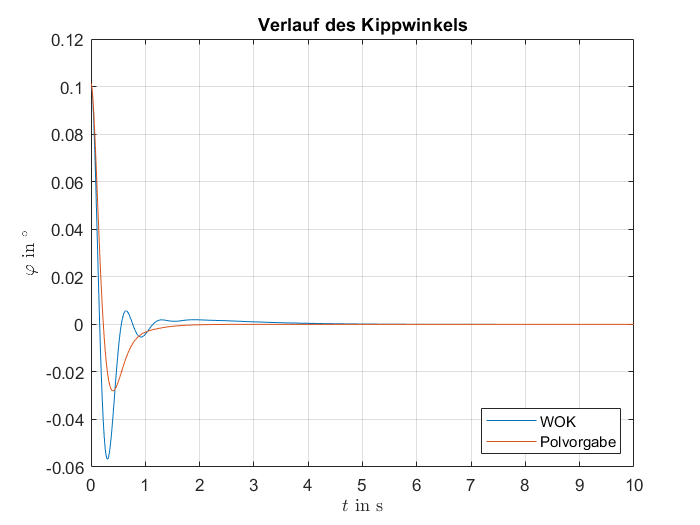

% Plotten des Verlaufs des Kippwinkels
figure()
plot(phi_c*180/pi)
hold on
plot(phi_b*180/pi)
legend("WOK","Polvorgabe","Location","southeast")
title("Verlauf des Kippwinkels")
xlabel("$t$ in $\mathrm s$",'Interpreter','latex')
ylabel("$\varphi$  in  $^{\circ}$",'Interpreter','latex')
saveas(gcf,"./Plots/phi_c.svg")
grid on

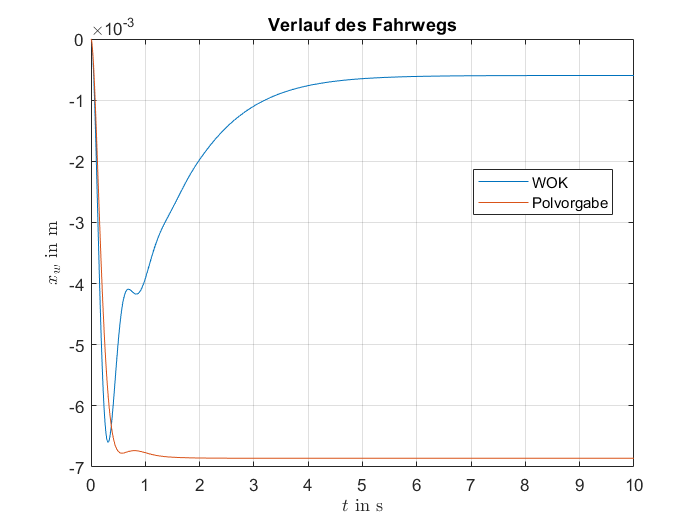


% Plotten des Verlaufs des Fahrwegs
figure()
plot(xw_c)
hold on
plot(xw_b)
legend("WOK","Polvorgabe","Location","best")
title("Verlauf des Fahrwegs")
xlabel("$t$ in $\mathrm s$",'Interpreter','latex')
ylabel("$x_w$  in  $\mathrm m$",'Interpreter','latex')
grid on
saveas(gcf,"./Plots/xw_c.svg")

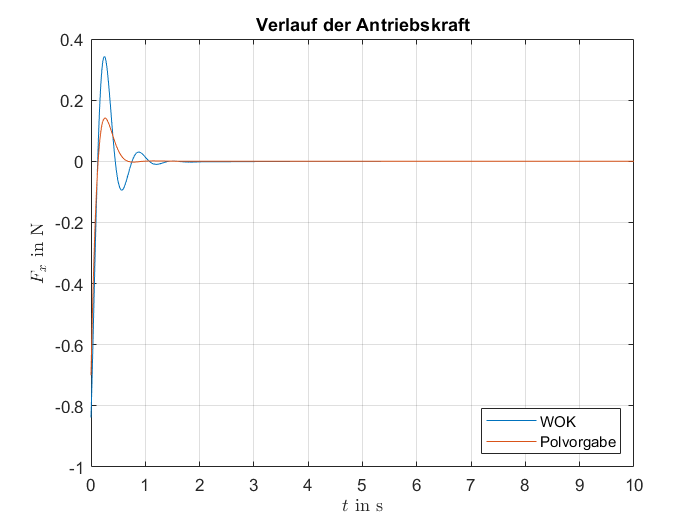


% Plotten des Verlaufs der Antriebskraft
figure()
plot(Fx_c)
hold on
plot(Fx_b)
legend("WOK","Polvorgabe","Location","southeast")
title("Verlauf der Antriebskraft")
xlabel("$t$ in $\mathrm s$",'Interpreter','latex')
ylabel("$F_x$  in  $\mathrm N$",'Interpreter','latex')
grid on
saveas(gcf,"./Plots/Fx_c.svg")


sim2b=get_param('Aufgabe2b','handle');
print(sim2b,'-dsvg','sim_2b');
sim2c=get_param('Aufgabe2c','handle');
print(sim2c,'-dsvg','sim_2c');